v0 = 80/3.6;         % initial velocity --> km/hr --> m/sec
p.gravity = 9.81;    % constant of gravity m/sec^2
p.mass = 1400/2;     % Vehicle mass in kg
p.theta = 2000/2;    % Inertia of vehicle in kg.m^2
p.a1 = 1.2;          % distance vehicle center front axle in m
p.a2 = 1.3;          % distance vehicle center reare axle in m
p.h = 0.55;          % height of vehicle center in m
p.cs1 = 20000;       % suspension stiffness of front axle in N/m
p.ds1 = 3000;        % suspension damping force of front axle in N.s/m
p.cs2 = 25000;       % suspension stiffness of reare axle in N/m
p.ds2 = 3200;        % suspension damping force of reare axle in N.s/m
p.thetaW = 1.2;      % wheel inertia in kgm ^2
p.r0 = 0.3;          % unloaded wheel radius in m
% long. tyre characteristics for pay load fz = fzn only
p.fzn = 3000;        % pay load in N
muf = 1.0;           % friction adjustment factor 
p.dfx0 = 100000;     % initial inclination long. force char in N/-
p.fxm = 3200 * muf;  % maximum long. force in N
p.sxm = 0.1 * muf;   % sx where fx = fxm
p.fxs = 3000 * muf;  % long. sliding force in N
p.sxs = 0.8 * muf;   % sx @ fx = fxs
p.cx = 160000;       % long. tyre stiffness in N/m
p.dx = 500;          % long. tyre damping in N.s/m
p.vn = 0.01;         % fictitious velocity in m/sec
% stedy state wheel loads 
p.fz0 = p.mass * p.gravity / (p.a1 + p.a2) * [p.a2  p.a1];
% appropriate " damping " constant in enhanced braking torque model
p.dn = p.r0 * sqrt(p.cx * p.thetaW);

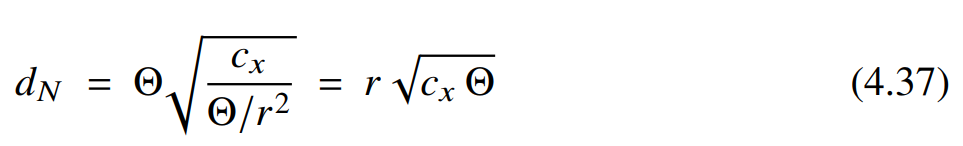

The numerical damping of the enhanced braking torque model as well as the amount of

the braking torque increase and decrease are adjusted to the wheel and tire parameter.  

% brake control via simple three - point ABS - like control
p.dtqb_inc = p.r0 * p.fxm / 0.1; % braking torque increase in N.m/sec
p.dtqb_dec = p.dtqb_inc / 2;     % braking torque decrease in N.m/sec

As in practice, the braking torque decrease is smaller than (here just the half of)

the braking torque increase.  

% set braking torque via lookup table : time t in s, torque value in Nm
p.tqb_t = [ 0.0 0.05 0.10 0.80 0.85 1.00 ] * round (1.5 + v0 / (muf * p.gravity));
p.tqb_v = [ 0.0 0.00 1.00 1.00 0.00 0.00 ] * 2 * p.fxm * p.r0;
% simulation interval and initial states
hstep = 0.01; 

Because the three-point control is anything but smooth, Heun’s method with a step

size of 1 ms (hstep=0.001) is used here instead of a standard MATLAB ode-solver.  

iout = 25;  t = 0;  tE = max(p.tqb_t);  
N = round(tE / (iout * hstep)) + 1;
x = [0 ; 0 ; 0 ; v0 ; 0 ; 0 ; v0 / p.r0 ; v0 / p.r0 ; 0 ; 0 ; 0 ; 0 ];
% pre - allocate vars to speed up loop
tout = zeros(N , 1);    xout = zeros(N , length(x));
sxi = zeros(N , 2);
fxi = sxi;
fzi = sxi;
TBi = sxi;
xpi = zeros ( size ( xout ));
disp(['time simulation: t = 0 to t =' , num2str(tE)])

time simulation: t = 0 to t =4


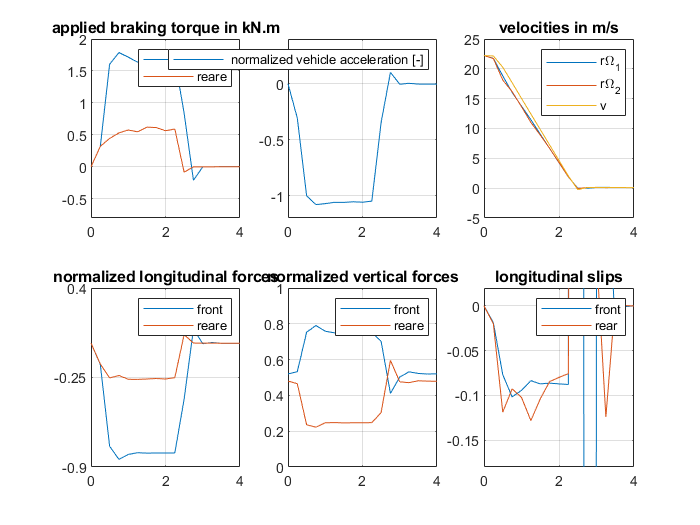

for io = 1 : N
  [xdot , out] = fun_08_abs_brake_dyn(t,x,p);    % generate output
tout(io) = t;
xout(io , :) = x.';
sxi(io , :) = out.sx.';
fxi(io , :) = out.fx.';
fzi(io , :) = out.fz.';
TBi(io , :) = out.TB.';
xpi(io , :) = xdot.';
if io < N   % simple Heun - solver ( second order constant step size )
    for i = 1 : iout
        xdot1 = fun_08_abs_brake_dyn (t,x,p);
        t = t + hstep ;
        xdot2 = fun_08_abs_brake_dyn (t,x + hstep * xdot1 ,p);
        xdot = 0.5*( xdot1 + xdot2 );   
        x = x + hstep * xdot ;
    end
end
end
% plot some result 
subplot(2 , 3 , 1)
plot(tout , TBi(: , 1 : 2) / 1000) 
grid on 
ylim([-0.8 , 2])
title('applied braking torque in kN.m') 
legend('front' , 'reare')
subplot(2 , 3 , 2)
plot(tout , xpi(: , 4) / p.gravity) 
grid on 
ylim ([ -1.2 ,0.4])
legend (' normalized vehicle acceleration [-]')
subplot(2 , 3 , 3)
plot(tout , [p.r0* xout(: , 7 : 8) , xout(: , 4)]) 
grid on 
ylim([-5 , 25])
title('velocities in m/s') 
legend('r\Omega_1 ' , 'r\Omega_2 ' , 'v')
subplot(2 , 3 , 4)
plot (tout , fxi(: , 1 : 2) / (p.mass * p.gravity)) 
grid on 
ylim([ -0.9 , 0.4]) 
title('normalized longitudinal forces') 
legend('front' , 'reare')
subplot(2 , 3 , 5)
plot(tout , fzi(: , 1 : 2) / (p.mass * p.gravity)) 
grid on
ylim([0 , 1]) 
title('normalized vertical forces') 
legend('front' , 'reare')
subplot(2 , 3 ,6)
plot(tout , sxi(: , 1 : 2)) 
grid on 
ylim([-0.18 , 0.02])
title('longitudinal slips')  
legend ('front' , 'rear') 